# TdCII- ARCO PARABOLICO INCERNIERATO

% Arco di forma parabolica schematizzato come una trave flessibile (e inestensibile)
% ad asse curvilineo
% di rigidezza flessionale EJ.

## Clear workspace and close any open windows

clear all
close all

## SIMBOLICO

syms a b c z real

## Valori numerici 

L=17; 
f=2;
p=(1.25*7.5);
E=210000000; % [KN/m^2] modulo elastico acciaio
J=5297/(10^4); % [m^4] inerzia sezione tubolare con Di=219,1 mm e t=16 mm

## Determino l'equazione della nostra parabola

F(z)=a*z^2+b*z+c; % Equazione della parabola 
% SISTEMA D'EQUAZIONI PER TROVARE LA FUNZIONE DELLA PARABOLA DATA 
% fisso che la cordinata x del vertice della parabloa passi per un determinato punto
E1=-b/(2*a)==0; 
% fisso che la parabola passi per il colmo
E2=F(0)==0;
% fisso che la parabola passi per punto A ''il nostro vincolo'' 
E3=F(L/2)==f; 
% Risolvo il sistema
S=solve([E1 E2 E3],[a b c]);
a_1=S.a(1);
b_1=S.b(1);
c_1=S.c(1);
% L'equazione della parabola diventa:
G(z)=simplify(subs(F,[a b c],[a_1 b_1 c_1]))

$$G(z) = \frac{8\,z^{2}}{289}$$

## Derivate della funzione parabolica

D1=simplify(diff(G,z)); % Derivata prima 
D2=simplify(diff(D1,z)); % Derivata seconda 

## PARAMETRIZZAZIONE DELLA CURVA

con x=t e y=f(t)

tan=D1;           % porto tang_θ in funzione di z
ds=(sqrt(1+D1^2)); % porto ds in funzione di z 
SIN(z)=D1/ds;       % porto sin_θ in funzione di z 
COS(z)=1/ds;         % porto cos_θ in funzione di z
phi=atan(D1/1); 
Dphi=simplify(diff(phi,z)); % derivata di phi
k(z)=Dphi/ds; %curvatura



## SISTEMA FO

syms VA VC HA real
% equazione alla traslazione orizzontale 
E4=HA==0;
% equazione alla traslazione verticale 
E5=L*p-(VA +VC)==0;
% equazione alla rotazione in A 
E6=L*VC-(L^2)*p/2==0;
% Risolvo il sistema
SO=solve([E4 E5 E6],[VA VC HA]);
HA0=SO.HA(1);
VA0=double(SO.VA(1));
VC0=double(SO.VC(1));

## CDS in F0

br=(L/2-z);
M0(z)=(-((p*br^2)/2)+VA0*(br));
% N0(z)=-VC0*SIN(br)+p*br*SIN(br);
% T0(z)=-VC0*COS(br)+p*br*COS(br);
 N0(z)=-VC0*SIN(br);
 T0(z)=-VC0*COS(br);

## SISTEMA F1

% equazione alla traslazione orizzontale 
E7=HA-1==0;
% equazione alla traslazione verticale 
E8=-VA-VC==0;
% equazione alla rotazione in A 
E9=VC*L==0;
% Risolvo il sistema
S1=solve([E7 E8 E9],[VA VC HA]);
HA1=S1.HA(1);
VA1=S1.VA(1);
VC1=S1.VC(1);

## CDS in F1

% Momento in F1 
M1(z)=simplify(VC1*br-1*(f-G(z)));
N1(z)=-VC1*SIN(br)-1*COS(br);
T1(z)=-VC1*COS(br)+1*SIN(br);

## MULLER-BRESLAU

Lv10=int(M1(z)*M0(z)/(E*J)*ds,z,-L/2,L/2);
Lv11 =int(M1(z)^2/(E*J)*ds,z,-L/2,L/2); 
% Lv11 è difficile da calcolare, 
n10 =Lv10 ; n11 =Lv11;
% n1=n10+X1*n11==0;
X1=double(-n10/n11);

## CALCOLO DELLE REAZIONI VINCOLARI ESATTE 

VAE=double(VA0+X1*VA1); % VA esatto
HAE=double(HA0+X1*HA1); % HA esatto 

## CALCOLO DELLE CDS ESATTE

ME(z)=M0(z)+X1*M1(z); % Momento esatto
NE(z)=N0(z)+X1*N1(z); % Forza normale esatta
TE(z)=T0(z)+X1*T1(z); % Taglio esatto

## PLOT FORZA NORMALE

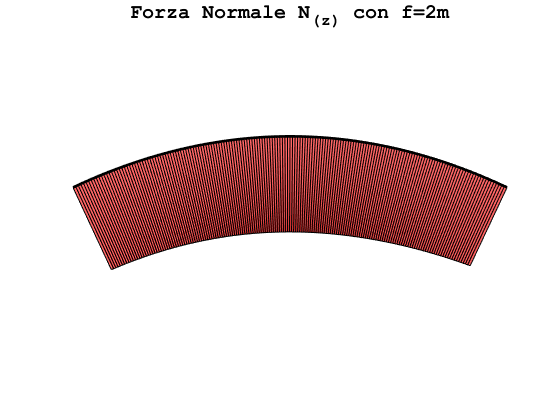

a=-L/2:0.1:L/2;       
ang(z)=atan(D1);
angle=ang(a);
N0n=double(NE(a));
figure(1)
c=1/50;
fig = gcf; % current figure handle
fig.Color = [1 1 1];
fig.ToolBar = 'none';
Y(z)=G(z);
for n=1:length(a)-1 
 B=double([a(n) a(n+1)  (a(n+1)+c*N0n(n+1)*sin(angle(n+1)))  (a(n)+c*N0n(n)*sin(angle(n+1)))]);
 C=double([Y(a(n)) Y(a(n+1))  (Y(a(n+1))-c*N0n(n+1)*cos(angle(n+1)))  (Y(a(n))-c*N0n(n)*cos(angle(n)))]);
hpatch=patch(B,C,'r','Facealpha',0.6);
axis equal
axis off
hold on  
end
%Struttura
plot(a,Y(a),'-k','LineWidth',2)
title(['\fontname{Courier}\fontsize{15}Forza Normale N_(_z_) con f=2m'],'color','K');
axis equal
axis ij
hold on

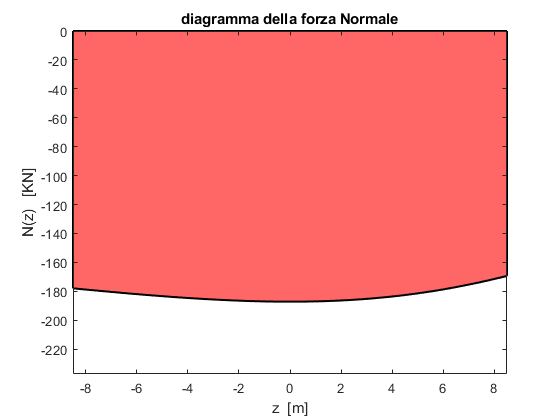

% plot per i valori
figure(2)
area(a,N0n,'FaceColor', 'r','LineWidth',1.5)
alpha(.6)
title('diagramma della forza Normale')
xlabel('z  [m]')
ylabel('N(z)   [KN]')
axis([min(a) max(a) (min(N0n)-50) 0])
hold on

## PLOT MOMENTO

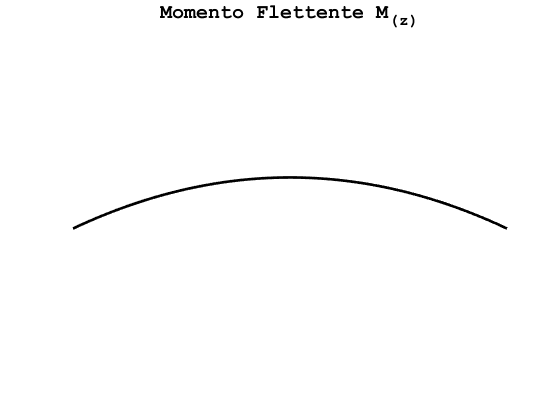

%% Plot M
M0n=double(ME(a));
figure(3)
c=1/50;
fig = gcf; % current figure handle
fig.Color = [1 1 1];
fig.ToolBar = 'none';

for n=1:length(a)-1 
    MM=M0n(n);
 B=double([a(n) a(n+1)  (a(n+1)+c*M0n(n+1)*sin(angle(n+1)))  (a(n)+c*M0n(n)*sin(angle(n+1)))]);
 C=double([Y(a(n)) Y(a(n+1))  (Y(a(n+1))-c*M0n(n+1)*cos(angle(n+1)))  (Y(a(n))-c*M0n(n)*cos(angle(n)))]);
 if MM<0
hpatch=patch(B,C,'r','Facealpha',0.8);
 else
hpatch=patch(B,C,'b','Facealpha',0.4);
 end
axis equal
axis ij
hold on  
end
%Struttura
plot(a,Y(a),'-k','LineWidth',2)
title(['\fontname{Courier}\fontsize{15}Momento Flettente M_(_z_)'],'color','K');
axis equal
axis off
hold on

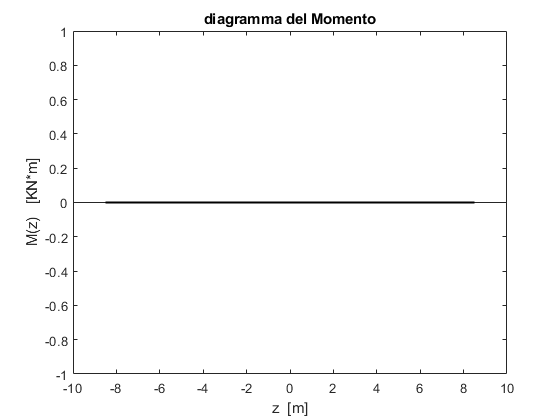

% plot per i valori
figure(4)
area(a,M0n,'FaceColor', 'b','LineWidth',1.5)
alpha(.4)
title({'diagramma del Momento'})
xlabel('z  [m]')
ylabel('M(z)   [KN*m]')

## PLOT TAGLIO

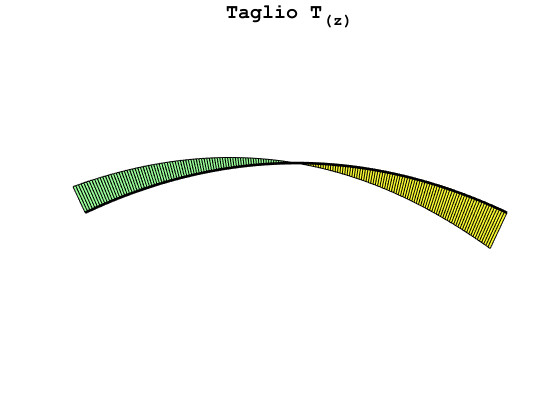

%% Plot M
T0n=double(TE(a));
figure(5)
c=1/50;
fig = gcf; % current figure handle
fig.Color = [1 1 1];
fig.ToolBar = 'none';

for n=1:length(a)-1 
    TT=T0n(n);
 B=double([a(n) a(n+1)  (a(n+1)+c*T0n(n+1)*sin(angle(n+1)))  (a(n)+c*T0n(n)*sin(angle(n+1)))]);
 C=double([Y(a(n)) Y(a(n+1))  (Y(a(n+1))-c*T0n(n+1)*cos(angle(n+1)))  (Y(a(n))-c*T0n(n)*cos(angle(n)))]);
 if TT<0
hpatch=patch(B,C,'y','Facealpha',0.8);
 else
hpatch=patch(B,C,'g','Facealpha',0.4);
 end
axis equal
axis off
hold on  
end
%Struttura
plot(a,Y(a),'-k','LineWidth',2)
title(['\fontname{Courier}\fontsize{15}Taglio T_(_z_)'],'color','K');
axis equal
axis ij
hold on

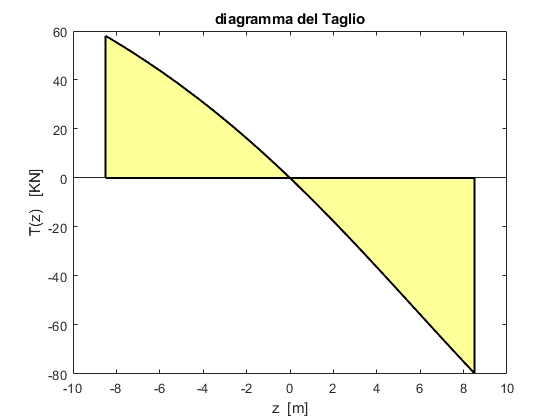

% plot per i valori
figure(4)
area(a,T0n,'FaceColor', 'y','LineWidth',1.5)
alpha(.4)
title({'diagramma del Taglio'})
xlabel('z  [m]')
ylabel('T(z)   [KN]')

## DEFORMATA

 syms A B real
v(z)=A*sin(k(z)*z)+B*cos(k(z)*z)

$$v(z) = B\,\cos\left(\frac{4624\,z}{\left(256\,z^{2}+83521\right)\,\sqrt{\frac{256\,z^{2}}{83521}+1}}\right)+A\,\sin\left(\frac{4624\,z}{\left(256\,z^{2}+83521\right)\,\sqrt{\frac{256\,z^{2}}{83521}+1}}\right)$$

%condizioni al contorno
A1=v(-L/2)==0

$$A1 = B\,\cos\left(\frac{2312\,\sqrt{353}}{124609}\right)-A\,\sin\left(\frac{2312\,\sqrt{353}}{124609}\right)=0$$

A2=v(L/2)==0

$$A2 = B\,\cos\left(\frac{2312\,\sqrt{353}}{124609}\right)+A\,\sin\left(\frac{2312\,\sqrt{353}}{124609}\right)=0$$

% Risolvo il sistema
AA1=solve([A1 A2],[A B]);
Ae=AA1.A(1);
Be=AA1.B(1);
ve=subs(v,[A B],[Ae Be])

$$ve(z) = 0$$

% % plot per i valori
% figure(5)
% plot(a,ve*1000,'FaceColor', 'y','LineWidth',1)
% alpha(.4)
% title({'deformata'})
% xlabel('z  [m]')
% ylabel('v(z)   [mm]')

